sensor_calibration_data = struct with fields:
           A_mag: [3×3 double]
         R_accel: [3×3 double]
        R_accel2: [3×3 double]
          R_gyro: [3×3 double]
           R_mag: [3×3 double]
           R_psi: 0.0814
      R_tof_left: 4.4603e-06
    R_tof_middle: 7.7185e-05
     R_tof_right: 1.6871e-05
          Rotw_a: [3×3 double]
         Rotw_a2: [3×3 double]
        Rotw_mag: [3×3 double]
     accel2_bias: [0.4372 0.3573 -10.2280]
      accel_bias: [0.0275 -0.3963 -10.0025]
           b_mag: [-5.3039e-05 6.3720e-05 -1.0369e-05]
       gyro_bias: [-0.0112 -0.0013 -0.0019]


Testing file: task2_3.mat


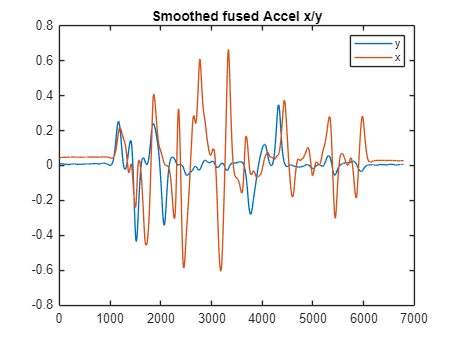

gyro_z =    -0.0019
   -0.0019
    0.0006
    0.0006
   -0.0019
   -0.0019
    0.0006
    0.0006
    0.0006
    0.0006


     1     0     0     0     0
     0     1     0     0     0
     0     0     1     0     0
     0     0     0     1     0
     0     0     0     0     1

z_pred:    1.1719
    1.9232
    1.2281

z_meas:    1.1620
    1.9130
    1.2180

Printing K:    0.5000   -0.0000   -0.5000
   -0.5000    1.0000   -0.5000
    0.1202   -0.0000   -0.1202
   -0.1202    0.2403   -0.1202
   -0.0001    0.0002   -0.0003

z_pred:    1.1689
    1.9121
    1.2311

z_meas:    1.1630
    1.9060
    1.2250

Printing K:    0.5000   -0.0000   -0.5000
   -0.5000    1.0000   -0.5000
    0.2289   -0.0000   -0.2289
   -0.2290    0.4579   -0.2290
    0.0031   -0.0048    0.0023

z_pred:    1.1699
    1.9231
    1.2301

z_meas:    1.1600
    1.9130
    1.2200

Printing K:    0.5000   -0.0000   -0.5000
   -0.5000    1.0000   -0.5000
    0.3157   -0.0000   -0.3156
   -0.3158    0.6315   -0.3157
    0.0064   -0.0106    0.0047

z_pred:    1.1678
    1.9281
    1.2322

z_meas:    1.1600
    1.9100
    1.2290

Printing K:    

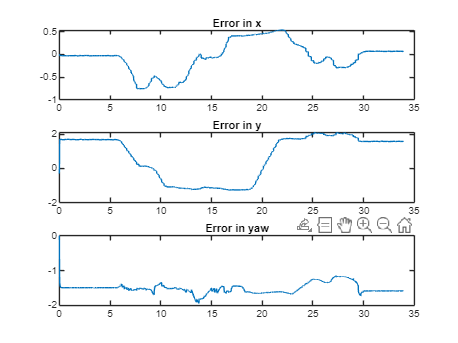

Absolute RMSE for task2_3.mat: 0.1465 m


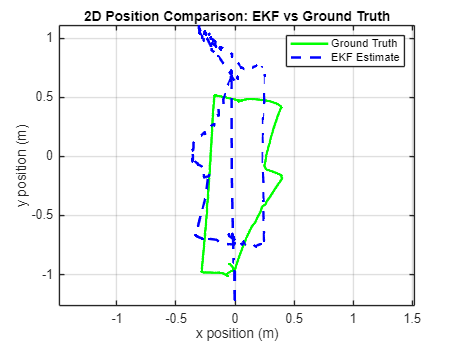

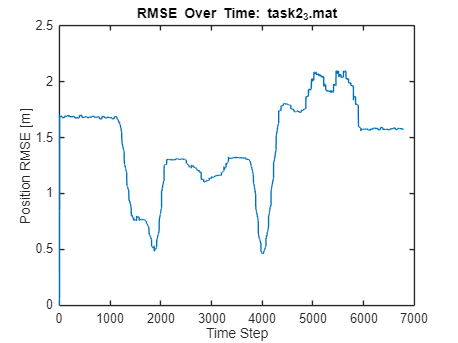

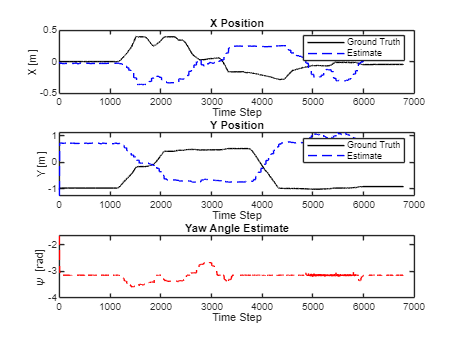

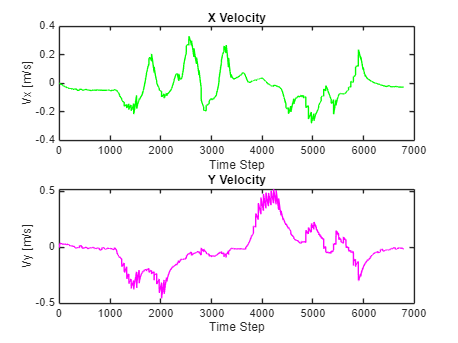

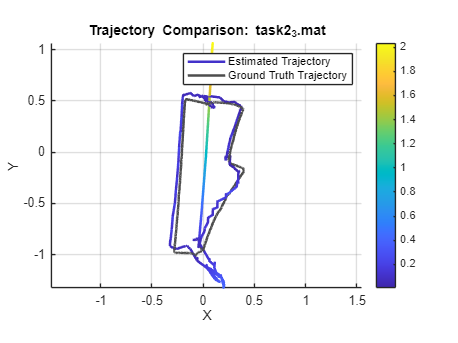

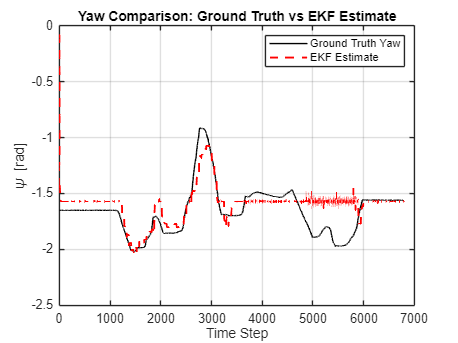

clear;clc; %Eval Script

taskFiles = { %'calib2_straight.mat'
    'task2_3.mat'%, 'task1_2.mat', 'task1_3.mat', 'task1_4.mat', ...
    %'task2_1.mat', 'task2_2.mat', 'task2_3.mat', 'task2_4.mat'
};

sensor_calibration_data = load('sensor_calibration.mat')


for k = 1:length(taskFiles)
    fprintf('\n==============================\n');
    fprintf('Testing file: %s\n', taskFiles{k});
    fprintf('==============================\n');

    try
        % Load the task file
        load(taskFiles{k}, 'out');


        % Call your EKF implementation
        warning('off', 'MATLAB:nearlySingularMatrix');  % disables that specific warning
        warning('on', 'all');                          % disables ALL warnings (if needed)


        [X_Est, P_Est, GT, gyro_z] = myEKF_nomag(out,diag([1, 1, 1.0, 1.0, 1]),diag([1,1,1]),1);



        % Convert ground truth to rigidtform3d
        pos = GT(:,1:3);
        N = size(pos,1);
        gtTforms(N) = rigidtform3d;
        for i = 1:N
            tGT = pos(i,:);
            RGT = eye(3);
            gtTforms(i) = rigidtform3d(RGT, tGT);
        end

        % Convert estimated states to rigidtform3d
        estTforms(N) = rigidtform3d;
        for i = 1:N
            tEst = [X_Est(i,1), X_Est(i,2), 0];
            R = eye(3);
            estTforms(i) = rigidtform3d(R, tEst);
        end

        % Compare trajectories
        metrics = compareTrajectories(estTforms, gtTforms, 'AlignmentType', 'rigid');
        fprintf('Absolute RMSE for %s: %.4f m\n', taskFiles{k}, metrics.AbsoluteRMSE(2));
        % Extract x and y from the state estimate and ground truth
        x_est = X_Est(:,1);
        y_est = X_Est(:,2);
 
        x_gt = GT(:,1);
        y_gt = GT(:,2);
        
        % Plotting
        figure;
        plot(x_gt, y_gt, 'g-', 'LineWidth', 2); hold on;
        plot(x_est, y_est, 'b--', 'LineWidth', 2);
        legend('Ground Truth', 'EKF Estimate');
        xlabel('x position (m)');
        ylabel('y position (m)');
        title('2D Position Comparison: EKF vs Ground Truth');
        axis equal;
        grid on;


        % RMSE over time
        positionErrors = sqrt(sum((X_Est(:,1:2) - GT(:,1:2)).^2, 2));
        figure;
        plot(1:N, positionErrors);
        title(['RMSE Over Time: ', taskFiles{k}]);
        xlabel('Time Step'); ylabel('Position RMSE [m]');

        % Visualisation of all states
        figure;
        subplot(3,1,1);
        plot(1:N, GT(:,1), 'k-', 1:N, X_Est(:,1), 'b--');
        title('X Position'); legend('Ground Truth','Estimate'); xlabel('Time Step'); ylabel('X [m]');

        subplot(3,1,2);
        plot(1:N, GT(:,2), 'k-', 1:N, X_Est(:,2), 'b--');
        title('Y Position'); legend('Ground Truth','Estimate'); xlabel('Time Step'); ylabel('Y [m]');

        subplot(3,1,3);
        plot(1:N, X_Est(:,5), 'r--');
        title('Yaw Angle Estimate'); xlabel('Time Step'); ylabel('\psi [rad]');

        % Velocity visualisation
        figure;
        subplot(2,1,1);
        plot(1:N, X_Est(:,3), 'g'); title('X Velocity'); xlabel('Time Step'); ylabel('Vx [m/s]');
        subplot(2,1,2);
        plot(1:N, X_Est(:,4), 'm'); title('Y Velocity'); xlabel('Time Step'); ylabel('Vy [m/s]');


        figure;
        plot(metrics, 'absolute-translation');
        title(['Trajectory Comparison: ', taskFiles{k}]);
        view(0,90)
        rotate3d on;

        figure;
        plot(1:N,(GT(:,4)), 'k-')
        hold on
        plot(1:N, (X_Est(:,5)+pi/2), 'r--', 'LineWidth', 1.5);
        hold off
        legend('Ground Truth Yaw', 'EKF Estimate');
        xlabel('Time Step');
        ylabel('\psi [rad]');
        title('Yaw Comparison: Ground Truth vs EKF Estimate');
        grid on;

     




    catch ME
        warning('Failed to process %s: %s', taskFiles{k}, ME.message);
    end
end

